Variables del sistema

nombre = "test5.mp4"

nombre = "test5.mp4"

segundo_inicial = 11

segundo_inicial = 11

Video grabado

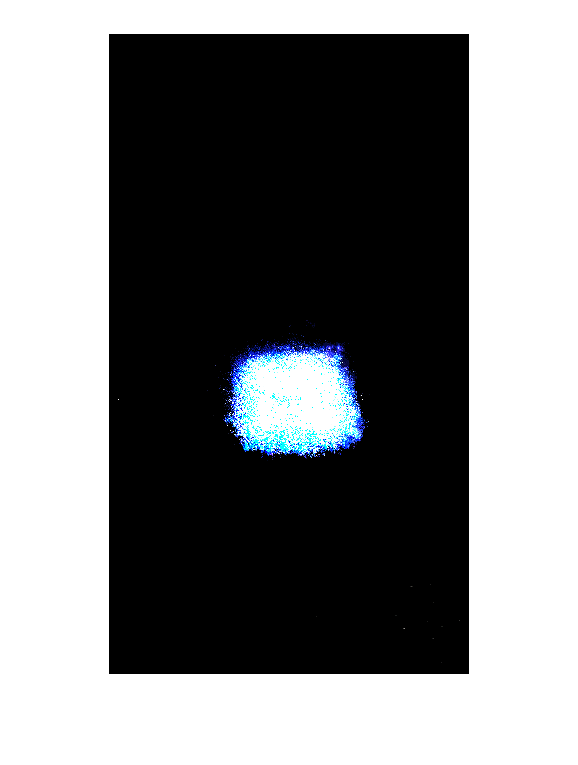

vidObj = VideoReader(nombre,"CurrentTime",segundo_inicial);
imgRef = im2double(readFrame(vidObj));
img = imgRef;

while hasFrame(vidObj)
    img = im2double(readFrame(vidObj));
    imshow(img)
    pause(0.001)
end

Imagen de referencia

vidObj = VideoReader(nombre,"CurrentTime",segundo_inicial);
imgRef = im2double(readFrame(vidObj));
imshow(imgRef);

Video filtrado

vidObj = VideoReader(nombre,"CurrentTime",segundo_inicial);
imgRef = im2double(readFrame(vidObj));
img = imgRef;
k=0.2;

while hasFrame(vidObj)
    img = im2double(readFrame(vidObj));
    proc_img = (img-imgRef)*k;

    imshow(proc_img)
    pause(0.001)
end

Dibujo trazado

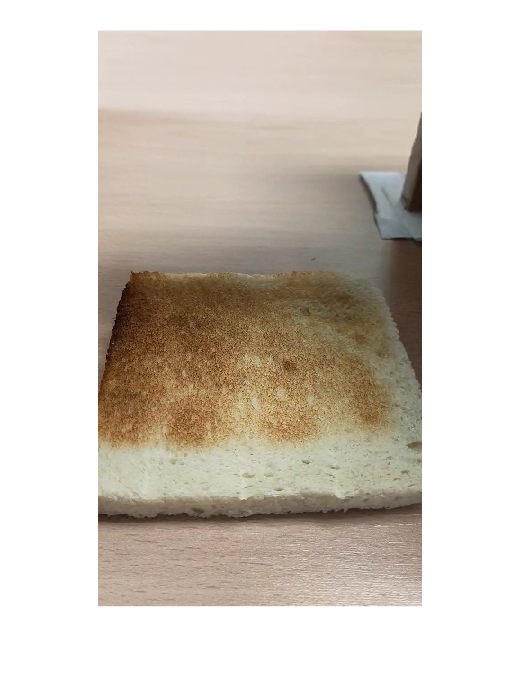

vidObj = VideoReader(nombre,"CurrentTime",segundo_inicial);
imgRef = im2double(readFrame(vidObj));
img = imgRef;

acc = zeros(h,w,3); % Cuiadado con el tamaño que se elige
imshow((imgRef))


i=1;
threshold = 0.1;
k = 0.5;
f = 0;

while hasFrame(vidObj)
    img = im2double(readFrame(vidObj));
    proc_img = (img-imgRef)*k;

    bin_img = proc_img(:,:,3) > threshold;
    
    acc = acc + proc_img.*bin_img;
    imshow(double(acc));
    pause(0.001)
end

% imshow(double(acc))
